clear;
close all;

%定义一些值
sampfreq=8e7; %80MHz
midfreq=5.1*1e9; %5.1GHz
freqspace=sampfreq/256;

c=3e8;
d=0.5; %m

derad = pi/180;      % 角度转弧度
attena = 3;          % 阵元个数
subcarrier = 30;     % 载波个数
source = 4;          % 信源数目

% 计算频率响应
Omega = @(tau) exp(-1i * 2 * pi * tau * freqspace);

% 计算角度响应
Phi = @(theta) exp(-1i * 2 * pi * (0:attena-1).'*d * sin(theta));

%生成待测序列
theta_m = [-20 -35 50 65];
tau_m = [10e-9 30e-9 5e-9 33e-9];
coef=[1;exp(1i*pi/6);exp(1i*pi/3); exp(1i*pi/2)];
snr = 10;
K = 1;

P = Phi(theta_m*derad);
O = repmat(Omega(tau_m),subcarrier,1);
exponents = (0:(subcarrier-1))';
O = O.^exponents;

% 对P和O的每一列进行Kronecker积，并拼合结果
A = [];  % 初始化A为空矩阵
for j = 1:source
    % 对第j列的P和O进行Kronecker积
    A_j = kron(P(:,j), O(:,j));
    % 将结果拼合到A矩阵中
    A = [A, A_j];
end

% % 输出结果
% disp('矩阵 A 的结构为：');
% disp(A);
S=randn(source,K);             %信源信号，入射信号
%S = sqrt(2)\(randn(1,K)+1i*randn(1,K)); 
X_in=A*S;                    %构造接收信号
% X1=awgn(X,snr,'measured'); %将白色高斯噪声添加到信号中


R = X_in * X_in'/K;
% 对协方差矩阵进行特征分解
[E, D] = eig(R);
[eigenvalues, idx] = sort(diag(D)', 'descend');

E = E(:,idx);
P = sum(eigenvalues);                           % 接收数据的总功率
P_cum = cumsum(eigenvalues);                    % 累积特征值
L = find((P_cum)/P>=0.95);                      % 选择主要分量的数量
L = L(1);                                       % 选择第一个满足条件的分量
Es = E(:,source+1:end);                             % 噪声子空间

% 定义搜索空间
theta_scan = -90:0.5:90; % 扫描角度范围-180-180
tau_scan = -1e-7:1e-9:1e-7; % 扫描时间延迟范围1ns-100ns

P_music = zeros(length(theta_scan), length(tau_scan)); % 初始化伪谱矩阵

% % 计算频率响应
% Omega = @(tau) exp(-1i * 2 * pi * tau * freqspace);
% 
% % 计算角度响应
% Phi = @(theta) exp(-1i * 2 * pi * ((0:M-1)*d/c) * midfreq * sind(theta));


for i = 1:length(theta_scan)
    % 计算当前扫描角度的角度响应矩阵
    a_theta_matrix = Phi(theta_scan(i)*derad);
    
    for j = 1:length(tau_scan)
        % 计算时间延迟响应
        a_tau = Omega(tau_scan(j)).^(0:(subcarrier-1))';
        
        % 克罗内克积生成联合导向向量
        a_scan = kron(a_theta_matrix, a_tau); 
        
        % 计算伪谱值
        P_music(i, j) = 1 / (a_scan' * (Es * Es') * a_scan);
    end
end

% 找到伪谱函数的最大值
[max_value, max_index] = max(P_music(:));
[theta_index, tau_index] = ind2sub(size(P_music), max_index);
estimated_theta = theta_scan(theta_index);
estimated_tau = tau_scan(tau_index);

% 显示估计结果
fprintf('Estimated AoA: %.2f degrees\n', estimated_theta);

Estimated AoA: -26.50 degrees


fprintf('Estimated ToF: %.2e seconds\n', estimated_tau);

Estimated ToF: -2.40e-08 seconds


% 计算归一化后的MUSIC伪谱 (以dB为单位)
P_music_dB = 10*log10(abs(P_music) / max(max(abs(P_music))));

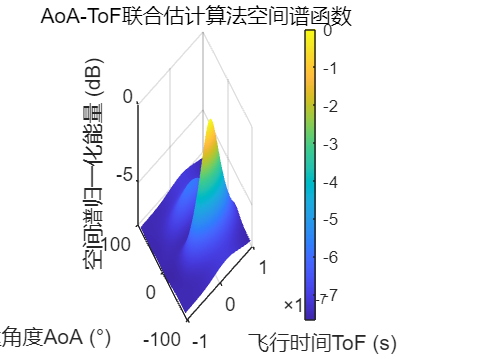

% 绘制三维MUSIC伪谱
figure;
surf(-tau_scan, theta_scan, P_music_dB, 'EdgeColor', 'none'); % 三维显示伪谱
xlabel('飞行时间ToF (s)');
ylabel('到达角度AoA (°)');
zlabel('空间谱归一化能量 (dB)');
title('AoA-ToF联合估计算法空间谱函数');
colorbar; % 添加颜色条
view(-37.5, 45); % 默认视角